# Taxi Deployment 

## Data Extraction and Introduction 

To get started, navigate to the Taxi Project folder, and run the script **generateTaxiPickupTable.mlx**. 

*Note it may take a while to finish. *

This will create (and save) two tables: `pickupLocations` and `taxiPickups. `A preview and description of each table is given below. 

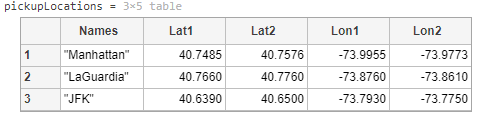

The table `pickupLocations` gives the latitude and logitude bounds for three pickup zones: 

- **Manhattan**: here meaning an area of high taxi traffic surrounding Penn Station, Grand Central Station, and the Port Authority Bus Terminal

- **LaGuardia**: meaning an area surrounding LaGuardia airport

- **JFK**: similarly meaning an area surrounding JFK airport. 

The zones are shown below for reference. 

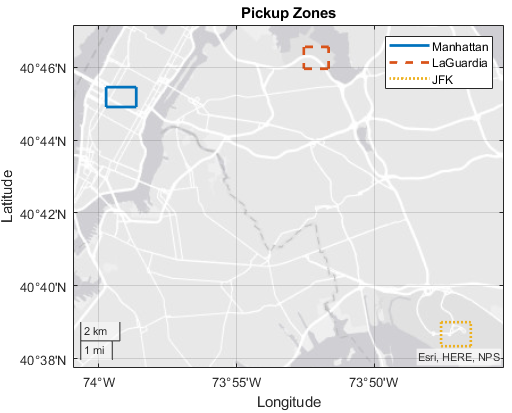

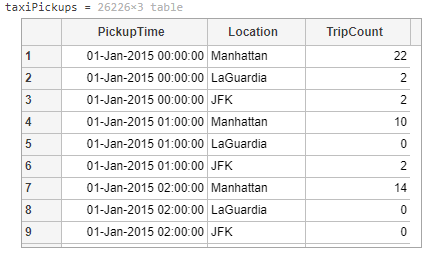

The table `taxiPickpus` represents the number of pickups in your data over one hour intervals of 2015 in the zones defined in `pickupLocations`. The start of each hour is specified in the `PickupTime` datetime variable, the zone is specified by the `Location` categorical variable, and the number of pickups is given by the `TripCount`. 

## Data Exploration and Partitioning 

The script **generateTaxiPickupTable.mlx **in the previous section saved copies of the tables to a MAT file named **taxiPickupData.mat**. To avoid having to run the script again if you continue working after clearing your workspace, the code below loads the saved data. 

% Make sure to follow the instructions in the previous section
if ~isempty(which('-all','taxiPickupData.mat'))
    load taxiPickupData.mat 
else
    error("The file taxiPickupData.mat is not found on the MATLAB path. Add it to the path or run generateTaxiPickupTable.mlx to generate it.")
end

### Visualization and Analysis

Analyze the data in the `taxiPickups` table. At a minimum, provide a visualization of the distribution (histogram) of the response variable `TripCount`, as well as a box plot for `TripCount` grouped by `Location`. 

### Separate Test Data 

Use `cvpartition` to separate 20% of the data set for testing later on, and create the training data. Ensure your results are repeatable by setting the random number generator seed to 10. Provide your code. 

## Models Training and Validation 

### Preprocessing 

As the focus of this course is machine learning, we’ve provided a function to do some feature engineering for you. Use **providedPreprocessing.mlx **to add the following features to your training/validation data set:

- `TimeOfDay` (numerical)

- `DayOfWeek` (categorical)

- `DayOfMonth` (numerical)

- `DayOfYear` (numerical) 

For example: 

### Model Training

Train models to predict `TripCount` using the processed test/validation data. Report your validation approach and the metrics for your best model. Your goal will be to get a validation $RMSE$ at or below $4.9$. Include code so that your script can reproduce your final model, including the model training. If using the app, export the training function and include a correct call to it in your script. Note you do not need to include the generated training function code itself in your script, just a correct call to it. For example, if you'd trained a tree model: 

## Model Testing and Evaluation 

### Testing

Preprocess the test data as needed, and use it to test your best model. Provide your code and report at least the $RMSE$ and $R^2$. You will need to achieve a test $RMSE$ at or below $4.9$ to receive full points here. 

### Evaluation

Discuss the results from training and testing. How well did your model generalize to new data? Include and discuss a plot of the residuals.

## Model Application, Results, and Analysis

### Apply Model 

As the focus of this course is machine learning, we’ve provided some skeleton code in this section. Below, we create a new table of staring features for 2016. 

*Note that you will need to use the variable names provided in comments or make your own additional edits to the code.*

taxiPickups2016 = table; 
taxiPickups2016.PickupTime = taxiPickups.PickupTime + years(1); 
taxiPickups2016.Location = taxiPickups.Location;
taxiPickups2016 = providedPreprocessing(taxiPickups2016) 

Choose your favorite day in 2016 and edit the variable `myDay` below which will be used to extract that day from the table. 

myDay = datetime("2016-12-6")
taxiPickupsMyDay = taxiPickups2016(day(taxiPickups2016.PickupTime,"dayofyear") == day(myDay,"dayofyear"),:)

Now, use your best model to predict `TripCount` on the day you've chosen and add it to the table. 

% taxiPickupsMyDay.TripCount = 


Again, to focus on machine learning, we have provided the necessary table manipulations and calculations below to use your model predictions to give the predicted fraction of trips happening in each hour on your selected day. 

Uncomment below once you have defined the table `taxiPickupsMyDay` above. 

% taxiPickupsMyDayTotals = groupsummary(taxiPickupsMyDay,"PickupTime","sum","TripCount");
% taxiPickupsMyDay = join(taxiPickupsMyDay,taxiPickupsMyDayTotals,"RightVariables","sum_TripCount")
% taxiPickupsMyDay.PickupFraction = taxiPickupsMyDay.TripCount./taxiPickupsMyDay.sum_TripCount
% taxiPickupsMyDayFractions = unstack(taxiPickupsMyDay,"PickupFraction","Location","GroupingVariables","PickupTime")

### Use the Results to Allocate Fleet

Now it is time to present to Mr. Walker. Discuss the results you were able to obtain, and provide recommendations how you would allocate the fleet of taxis on the chosen day. Provide your reasoning, and also present your case using at least one visualization, e.g. a [stacked bar plot](matlab: web(fullfile(docroot, 'matlab/ref/bar.html#bthxce9'))). 